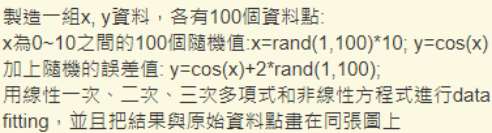

% 生成數據
x = 10 * rand(1, 100);               % 在 0 到 10 之間產生 100 個隨機值
y = cos(x) + 2 * rand(1, 100);       % 生成 y 值，加上隨機誤差值
disp('x 值:'); disp(x); 

x 值:
    7.0245    9.6136    1.3124    5.3241    2.9101    1.6618    5.0847    0.9536    8.5583    0.8238    1.1339    2.1939    4.2810    8.7942    9.0227    6.2443    7.7256    8.2499    5.6500    2.0854    3.0117    4.2039    2.3833    0.5977    8.2218    3.2600    4.8786    3.2353    6.8849    4.8144    1.5916    8.4665    4.4914    0.0497    2.6353    1.0848    0.5066    7.6298    6.2985    2.6459    0.1143    7.3979    2.9053    7.0704    9.3441    2.9347    5.5430    1.8975    5.6687    8.3002    7.6328    9.4895    5.4730    6.6132    5.5815    1.0818    4.3563    1.1258    3.6838    6.9287    4.0223    9.2970    4.3045    0.3468    7.0758    2.5454    2.4262    3.2059    1.0688    6.7738    8.6073    4.3752    0.0330    8.6126    2.3173    4.4141    2.4250    0.5683    5.3256    0.7608    0.9839    8.6658    0.9732    5.5784    0.3798    7.1335    0.8055    2.4053    7.7143    4.5772    1.0407    2.7457    2.9699    4.1342    4.6342    2.4911    8.3836    2.0455    0.4630    6

disp('y 值:'); disp(y);

y 值:
    2.0002   -0.8043    2.0682    1.9049    0.0103    0.6479    1.5042    0.8143    0.8241    2.4347    0.6068    0.6254    1.3748    0.7782    1.0428    2.7481    0.5696    0.2092    2.6089    0.4740   -0.1878    0.9294   -0.0891    1.7172    0.5252   -0.6649    0.2909    0.3639    0.9523    0.5705    1.5838    0.5172    0.5176    1.6909   -0.7116    0.5366    1.2849    1.1885    2.7011    0.3586    1.6486    1.4081   -0.4066    0.7210   -0.7963   -0.9134    0.8019    1.0965    2.0072   -0.3147    1.4419   -0.9004    1.8149    1.4784    2.4868    0.9505    1.2304    2.2624    0.0632    2.2310    0.8754   -0.2511    0.9888    2.6581    1.8011   -0.7398    0.5188    0.9606    1.2002    1.2444   -0.1286    1.3287    1.3489   -0.6629   -0.2520    0.2908   -0.3660    1.0149    1.8115    1.3719    1.3380    0.5667    1.6098    1.8430    1.4841    1.7628    1.3243    0.5083    2.0605    1.4221    1.5248   -0.5416   -0.8581    1.4375    1.3976    0.6935    0.8179   -0.2896    2.4191    2

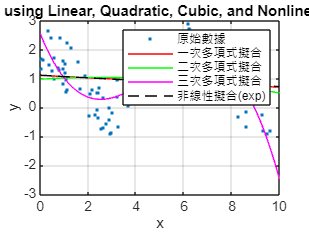


% 轉置
x = x';
y = y';

% 用線性一次、二次、三次多項式和非線性方程式進行 Data fitting，並把結果和原始資料畫在同一張圖上。
% 一次多項式擬合
p1 = fit(x, y, 'poly1');
% 二次多項式擬合
p2 = fit(x, y, 'poly2');
% 三次多項式擬合
p3 = fit(x, y, 'poly3');
% 非線性擬合 (exp)
pExp = fit(x, y, 'exp1');

% 繪圖
figure;
% 原始數據
plot(x, y, 'b.');
hold on;

plot(p1, 'r');
plot(p2, 'g');
plot(p3, 'm-');
plot(pExp, 'k--');
hold off;
% 圖例和標題
legend('原始數據', '一次多項式擬合', '二次多項式擬合', '三次多項式擬合', '非線性擬合(exp)');
title('Data Fitting using Linear, Quadratic, Cubic, and Nonlinear Equations');
xlabel('x');
ylabel('y');
grid on;